clear all
close all

Exercise 1

Let f(x) = ex - 1 and g(x) = 1 - x2 for x ∈ [0; 1]. Draw the graphs of the two functions f and g, determine the point of intersection z of the two graphs and calculate the area of the region between the two graphs in [0; z].

% Defining the system of functions
f = @(x) exp(x) - 1;
g = @(x) 1 - x.^2;

% Setting the interval for x
x = linspace(0, 1);
y1 = f(x);  % setting up y values
y2 = g(x);

%Plotting the functions
figure
plot(x, y1,'r', x, y2,'b')
xlabel('x')
ylabel('y')
legend('f(x)','g(x)','intersection')

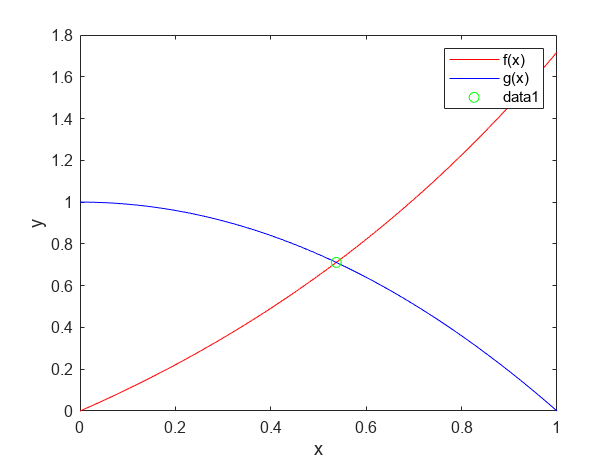


% The intersection of the two functions, determined by using the built-in 'fzero' MATLAB function
fun = @(x) f(x) - g(x);
z = fzero(fun, [0, 1]);
hold on
scatter(z, f(z), 'g')

% Display the intesection
disp(['Intersection point: ', num2str(z)])

Intersection point: 0.53727



% Find the area between the curves using the built-in 'trapz' MATLAB function
area = trapz(x(x <= z), min(y1(x <= z), y2(x <= z)));
% Display the area
disp(['Area: ', num2str(area)])

Area: 0.1727


Exercise 2

Briefly describe probability distributions with continuous random variables (Uniform distribution) The, Compare the “ probability density function” and the “Continuous uniform cumulative distribution function” of the following continuous uniform random variables: X1 ~ U(0, 1), X2 ~ U(-3, 2), X3 ~ U(2, 4), X4 ~ U(0.8, 1.5 Next, determine the the mean and variance values for the continuous uniform distribution.

close all
% PDF: Given a continuous random variable X, its probability density function f(x) is the function whose integral allows us to calculate the probability that X lie within a certain range, P(a≤X≤b).

%The curve y=f(x) serves as the "envelope", or contour, of the probability distribution.




% Setting up X for pdf:

p1= @(x) 1./(1 - 0).*(x >= 0 & x <= 1);
p2= @(x) 1./(2 - (-3)).*(x >= -3 & x <= 2);
p3= @(x) 1./(4 - 2).*(x >= 2 & x <= 4);
p4= @(x) 1./(1.5 - 0.8).*(x >= 0.8 & x <= 1.5) 

p4 = function_handle with value:
    @(x)1./(1.5-0.8).*(x>=0.8&x<=1.5)


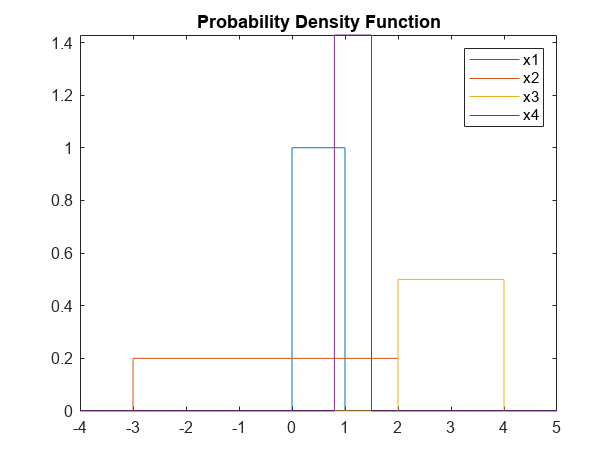


% Plot the probability density functions
x = linspace(-4, 5, 100);  %maximum values for X on x axis
figure
fplot(p1, [-4, 5])  %fplot built in function to plot functions
hold on
fplot(p2, [-4, 5])
fplot(p3, [-4, 5])
fplot(p4, [-4, 5])
title('Probability Density Function')
legend('x1', 'x2', 'x3', 'x4')

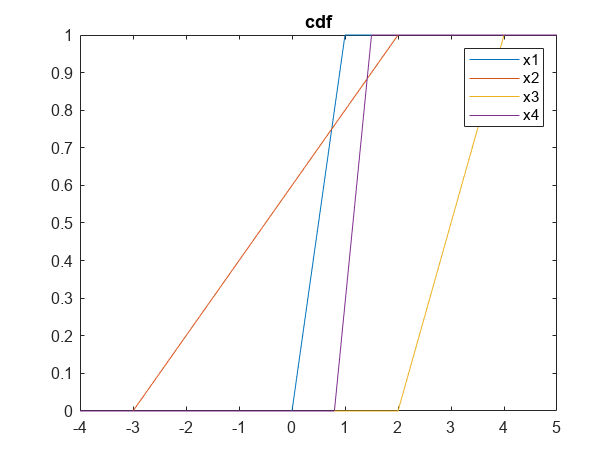


%CDF: CDF of a random variable  X’ is a function which can be defined as, FX(x) = P(X ≤ x)
%The right-hand side of the cumulative distribution function formula represents the probability of a random variable %X’ which takes the value that is less than or equal to that of the x.
%The semi-closed interval in which the probability of ‘X’ lies is (a.b], where a < b, 
%P(a < X ≤ b) = Fx(b) - Fx(a)



% Define the cdf
c1 = @(x) (x - 0)./(1 - 0).*(x >= 0 & x <= 1) + (x > 1);
c2 = @(x) (x - (-3))./(2 - (-3)).*(x >= -3 & x <= 2) + (x > 2);
c3 = @(x) (x - 2)./(4 - 2).*(x >= 2 & x <= 4) + (x > 4);
c4 = @(x) (x - 0.8)./(1.5 - 0.8).*(x >= 0.8 & x <= 1.5) + (x > 1.5);


% Plot the cdf
figure
fplot(c1, [-4, 5])
hold on
fplot(c2, [-4, 5])
fplot(c3, [-4, 5])
fplot(c4, [-4, 5])
title('cdf')
legend('x1', 'x2', 'x3', 'x4')



% mean: The mean of a continuous uniform distribution is given by:   m = (p + q)/2    ,where m, p and q are the mean,lower and upper bounds of the range, respectively.
% variance: The variance of a continuous uniform distribution is given by: sigma^2 = (q - p)^2/12 , where p and q are the lower and upper bounds of the range, respectively.

%mean:
m1 = (0 + 1)/2;
m2 = (-3 + 2)/2;
m3 = (2 + 4)/2;
m4 = ( 0.8+ 1.5)/2;


%variance:
v1= (1-0)^2/12;
v2 = (2-(-3))^2/12;
v3 =(4-2)^2/12;
v4 =(1.5-0.8)^2/12;

% Showing  the results
fprintf('x1: mean = %f, variance = %f\n', m1, v1)

x1: mean = 0.500000, variance = 0.083333


fprintf('x2: mean = %f, variance = %f\n', m2, v2)

x2: mean = -0.500000, variance = 2.083333


fprintf('x3: mean = %f, variance = %f\n', m3, v3)

x3: mean = 3.000000, variance = 0.333333


fprintf('x4: mean = %f, variance = %f\n', m4, v4)  

x4: mean = 1.150000, variance = 0.040833


Exercise 3:

Aliasing occurs when you don't sample a signal fast enough to be able to reconstruct it accurately after sampling. To avoid this problem, we must follow Nyquist's theorem, which states that we must sample at a rate at least twice the fastest frequency of the signal we are sampling. Considering the following signal characteristics: f = 2; % sine wave frequency fs = 3; % sample frequency tmax = 2; % go to 2 seconds Outputs: 1) plot the “original sine signal”; 2) plot “the original signal with Aliasing” (whose frequency is 1.5 times the highest frequency of the original signal); 3) let's consider the discrete Fourier transform of the original signal. Now, let's consider the original signal again. Using the fast Fourier transform (FFT) to obtain the discrete Fourier transform gives us this plot (Since the FFT only shows the positive frequencies, we need to shift the graph to get the correct frequencies.). Compare the DFT to the actual Fourier transform, what do you observe?

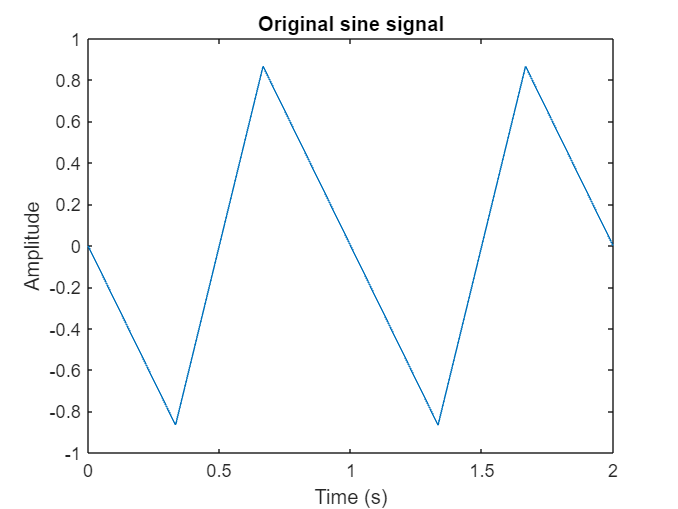

close all
% Given:
f = 2;
fs = 3;
tmax = 2;

%time vector;
tv =  0:1/fs:tmax;

% sine wave:
y1 = sin(2*pi*f*tv);

% Aliased sine wave
y2 = sin(2*pi*(1.5*f)*tv);

%Plot the original sine signal
plot(tv, y1)
xlabel('Time (s)')
ylabel('Amplitude')
title('Original sine signal')

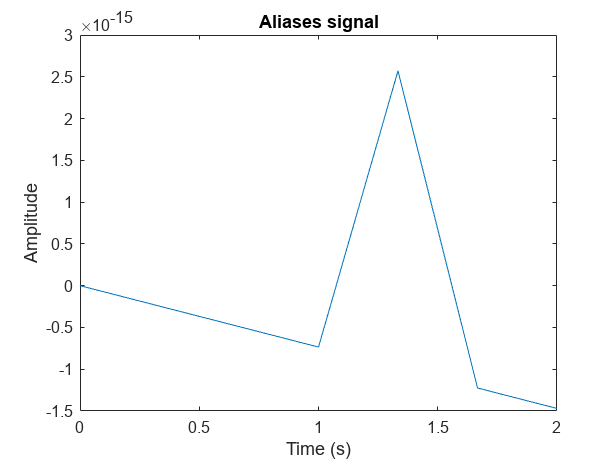



%% Plot the original signal with aliasing
plot(tv, y2)
xlabel('Time (s)')
ylabel('Amplitude')
title('Aliases signal')

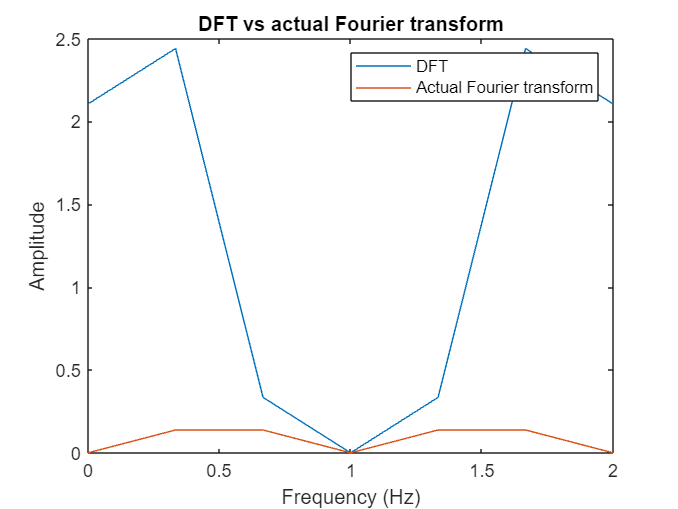



%
%The Fourier transform is a mathematical formula that transforms a signal sampled in time or space to the same signal sampled in temporal or spatial frequency. 
% In signal processing, the Fourier transform can reveal important characteristics of a signal, namely, its frequency components.

%dft

dfy1 = fft(y1);

%% Shift the dft for +ve and -ve frequencies
Y1 = fftshift(dfy1);

% Calculate the actual Fourier transform
Y2 = 1/(2*pi*sqrt(-1)*f).*(1 - exp(-2*pi*sqrt(-1)*f*tv)).*(tv >= 0 & tv <= tmax);

% Plot the DFT and the actual Fourier transform
figure
plot(tv, abs(Y1))
hold on
plot(tv, abs(Y2))
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('DFT vs actual Fourier transform')
legend('DFT', 'Actual Fourier transform')

hold off

Exercise 4

Using the data in the file 'gc-data-2.txt' 1) find lines that match certain patterns to identify the regions that are data, then we read in the data lines. 2) get the number of data points, and read up to the data; 3) initialize the data vectors and then read in the data; 4) plot the data and then correct for non-zero baseline 5) The plotted peaks are asymmetric, implement a fitting procedure using a decaying gaussian function 6) Implement a fitting procedure with two peaks (to get two peaks, you simply add two peaks together following the steps in point 5) 7) Plot fitting function with an initial guess for each parameter 8) use nonlinear fitting to get the parameters that best fit our data, and plot the fit on the graph 9) now extract out the two peaks and integrate the areas 10) Compute relative amounts

opts = detectImportOptions('gc-data-21.txt'); 
opts.DataLines = [60 61];
opts.VariableNames = {'Peak#',	'R.Time','I.Time','F.Time	Area','Height	A/H	Conc.','Mark'	,'ID#','Name','k','Plate #'	,'Plate Ht.',	'Tailing',	'Resolution',	'Sep.Factor'};
T_peaks = readtable('gc-data-21.txt',opts)

T_peaks = 2×17 table
    Peak_    R_Time    I_Time    F_TimeArea    HeightA_HConc_    Mark      ID_     Name        k           Plate_       PlateHt_     Tailing    Resolution    Sep_Factor    ExtraVar1    ExtraVar2    ExtraVar3
    _____    ______    ______    __________    ______________    _____    _____    ____    __________    __________    __________    _______    __________    __________    _________    _________    ____



opts2 = detectImportOptions('gc-data-21.txt'); 
opts2.DataLines = [75 10043];
opts2.VariableNames ={'R.Time','Intensity'};
T_Chromatogram = readtable('gc-data-21.txt',opts2)

T_Chromatogram = 9969×2 table
    R_Time     Intensity
    _______    _________

          0      -288   
    0.00167      -288   
    0.00333      -288   
      0.005      -288   
    0.00667      -320   
    0.00833      -288   
       0.01      -288   
    0.01167      -288   
    0.01333      -288   
      0.015      -288   
    0.01667      -288   
    0.01833      -288   
       0.02      -288   
    0.02167      -320   
    0.02333      -288   
      0.025      -288   


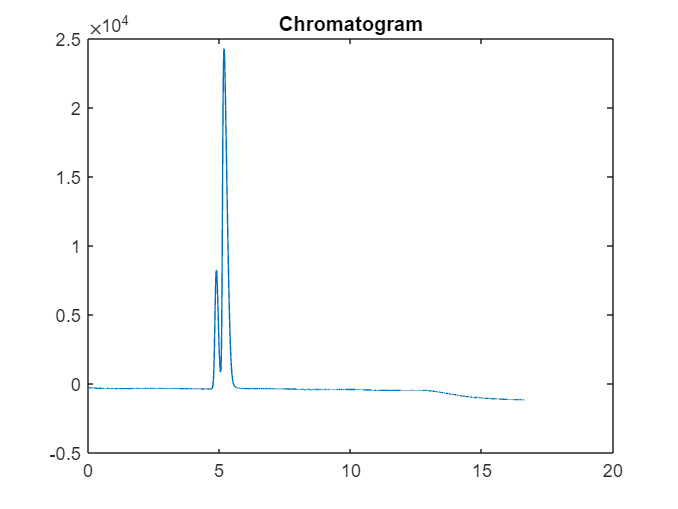



plot(T_Chromatogram.R_Time,T_Chromatogram.Intensity)
hold on
title("Chromatogram")
hold off